# Sistemas Realimentados - 2023/1

## Nome: João Gabriel Santos Custodio

## Data de entrega limite: 6/4

## Trabalho 1 

**Referências para ler para este trabalho**

- [Manual rápido do Matlab](https://drive.google.com/file/d/1_mXyft7ynFmkxGnCyx7BV8VyOKyIx9tj/view?usp=share_link)

- [Resposta transitória e estacionária](https://drive.google.com/file/d/19GToHEkcvTon0UK2nOmi1_l0k5dx3YIJ/view?usp=share_link)

## Resposta transitória e de regime de sistemas dinâmicos

Definições:

datetime('now')

ans = datetime
   06-Apr-2023 23:21:49


I=14;
[tau,zeta,wn,teta,p] = init(I);
g1=tf(p,[tau 1]);
g2=tf(wn^2,[1 2*zeta*wn wn^2]);
g0=tf(p,[tau 1],'InputDelay',teta);
g3=tf(p^3,poly(-[p p p]));
[y0,t0]=step(g0);
[y1,t1]=step(g1);
[y2,t2]=step(g2);


1) Obtenha a constante de tempo, o tempo de estabilização e o ganho do sistema cuja resposta ao degrau unitário é mostrada na figura 1.

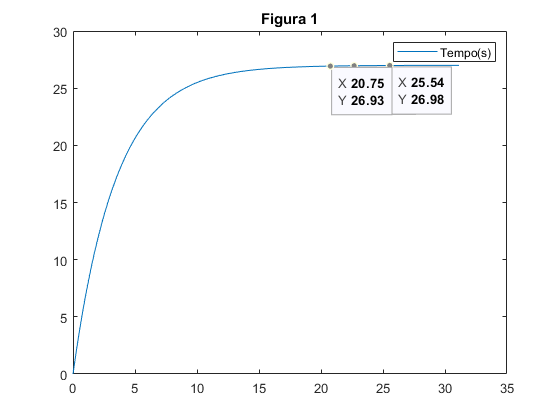

figure;
plot(t1,y1);legend('Tempo(s)');title('Figura 1');

Resposta:

Constante de tempo T:     5T = 20     T = 4

Tempo de estabilização = 20 segundos

Ganho do sistema = 27

2) Obtenha a constante de tempo, o tempo morto, o tempo de estabilização e o ganho do sistema cuja resposta degrau unitário é mostrada na figura 2.

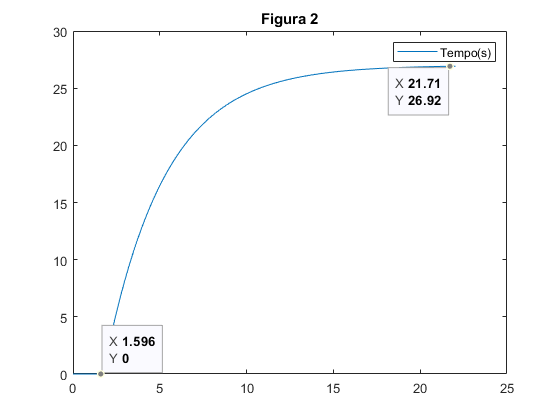

figure;
plot(t0,y0);legend('Tempo(s)');title('Figura 2');

Resposta:

Constante de Tempo: T = 4.

Tempo morto = 1,596 segundos.

Tempo de estabilização = 20 segundos.

Ganho do sistema = 21,71.

3) Obtenha o tempo de subida, a sobre-elevação (0 a 100%), o tempo de estabilização, o ganho do sistema cuja resposta ao degrau unitário é mostrada na figura 3.

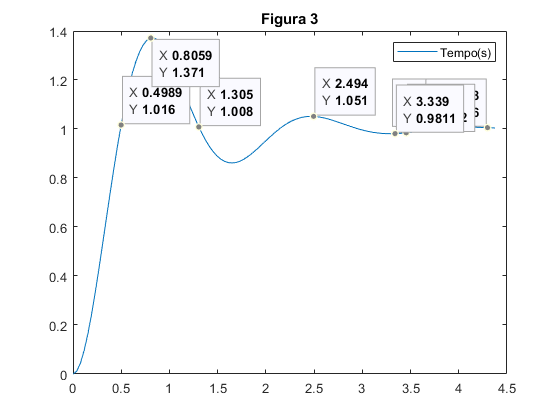

figure;
plot(t2,y2);legend('Tempo(s)');title('Figura 3');

Resposta:

Tempo de subida = 0,4985 segundos.

Sobre-elevação = ((1,371 - 1,006)/1,006) * 100% = 36,28%.

Tempo de estabilização = 3,33 segundos.

Ganho do sistema = 1.

4) Na figura 4  mostra-se o efeito do amortecimento $\zeta$na sobreelevação (UP) e tempo de estabilização (ts).  A relação UP com $\zeta$ é dada por $\textrm{UP}=100e^{-\zeta \pi /\sqrt{1-\zeta^2 }}$, e a relação de ts com $\zeta$é dada aproximadamente por $\textrm{ts}=\frac{4}{\zeta \omega_n }$, $0<\zeta <0\ldotp 9$.

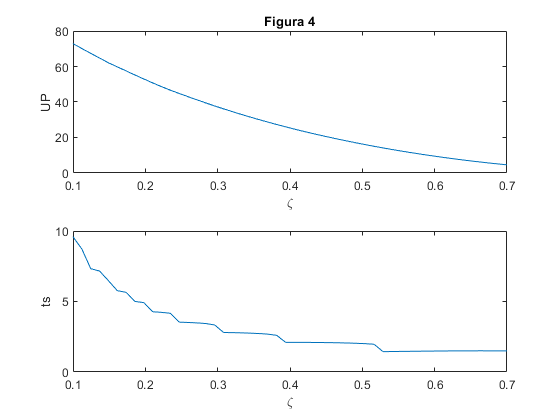

z=linspace(0.1,0.7,50);
ts=[];UP=[];
for i=1:50
    m=tf(wn^2,[1 2*z(i)*wn wn^2]);
    S=stepinfo(m);
    ts(i,1)=S.SettlingTime;
    UP(i,1)=S.Overshoot;
end
figure;
subplot(211);plot(z,UP);xlabel('\zeta');ylabel('UP');title('Figura 4')
subplot(212);plot(z,ts);xlabel('\zeta');ylabel('ts')

Explique, observando as figuras, como $\zeta$se relaciona com UP e ts, e obtenha a faixa de valores de $\zeta$para os quais a sobre-elevação esteja entre 40 e 50%, verificando a que faixa de valores de tempo de estabelecimento isso corresponde.

Resposta: 

Como o script faz com que os valores do amortecimento aumentem, espera-se que o tempo de acomodação e o tempo de sobre-elevação diminua, e de fato observando o gráfico 

temos isso sendo verificado, ou seja, quanto maior o valor do amortecimento, menor o tempo de acomodação e sobre-elevação.

Observando o gráfico, verifica-se que para os valores de $\zeta$ entre 0,21 e 0,28 temos a sobre-elevação na faixa de 40 e 50%.

Seja a localização do par de polos complexos de uma FT de um protótipo de segunda ordem mostrada na figura 5.

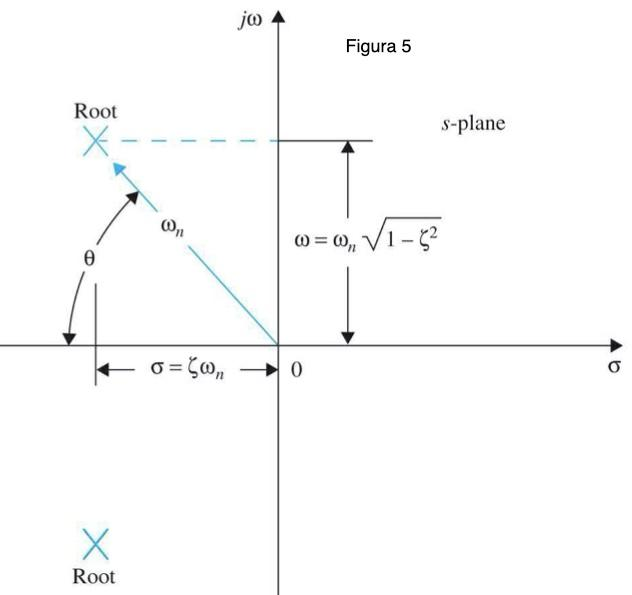

5) Use a expressão que relaciona de ts com $\zeta$e $\omega_n$ para explicar onde devem estar os polos de malha fechada para um menor tempo de estabilização. 

Resposta:


$$\textrm{ts}=\frac{4}{\zeta \omega_n }$$


A equação acima relaciona o tempo de estabilização com o $\zeta$e $\omega_n$. Note que temos uma relação inversamente proporcional, portanto, quanto maior o produto $\zeta \omega_n$ menor será o tempo de estabilização. Dessa forma, para maximizar o produto $\zeta \omega_n$ necessitamos de uma relação triangular para formarmos um triângulo retângulo com angulos de 45°, portanto segue e relação:


$$\begin{array}{l}
\zeta \omega_n =\omega_n \sqrt{1-\zeta ²}\\
\zeta ²=1-\zeta ²\\
\zeta =\frac{\sqrt{2}}{2}
\end{array}$$


Uma vez que sabemos o valor de $\zeta$, basta escolher o maior valor possível de $\omega_n$ e a região com os menores valores de tempo de estabilização serão varridos por esse $\omega_n$.

6) Sabendo que $\zeta =\cos \left(\theta \right)$, em que região do plano complexo devem estar os polos para que UP seja menor que 5%?

Resposta:

$\textrm{UP}=100e^{-\zeta \pi /\sqrt{1-\zeta^2 }}$, quermos que UP<5%


$$\begin{array}{l}
\mathrm{100}e^{-\zeta \pi /\sqrt{1-\zeta^2 }} <5\\
e^{-\zeta \pi /\sqrt{1-\zeta^2 }} <0,05\\
-\zeta \pi /\sqrt{1-\zeta^2 }-2,9957\\
\zeta \pi /\sqrt{1-\zeta ²}>2,9957\\
\zeta ²\pi ²/\left(1-\zeta ²\right)>8,9744\\
\zeta ²\left(\pi ²+8,9744\right)>8,9744\\
\zeta ²>\frac{8,9744}{\pi ²+8,9744}\\
\zeta_+ >\sqrt{\frac{8,9744}{\pi ²+8,9744}}\\
\zeta_+ >0\ldotp 6901\approx 0\ldotp 69\\
\mathrm{Como}\;\zeta =\mathrm{cos}\theta \\
\mathrm{cos}\left(\theta \right)>0\ldotp 69\\
A\;\mathrm{inequação}\;\mathrm{acima}\;é\;\mathrm{válida}\;\mathrm{para}\;\mathrm{os}\;\mathrm{seguintes}\;\mathrm{valores}\;\mathrm{de}\;\theta \;\mathrm{no}\;\mathrm{eixo}\;\mathrm{das}\;\mathrm{abscissas}:
\end{array}$$


acosd(0.69)

ans = 46.3699


$$\begin{array}{l}
-\mathrm{arccos}\left(0,69\right)<\theta <\mathrm{arccos}\left(0,69\right)\\
-46,37<\theta <46,37
\end{array}$$


Portanto, na região com os valores de $\theta$ entre o intervalo de [-46,37;46,37] temos que UP com valor inferior à 5%.

7) A figura 6 mostra a resposta ao impulso do sistema de segunda ordem do item 3. Explique como obter a resposta ao impulso a partir de G(s) usando a transformada de Laplace.

figure;impulse(g2);title('Figura 6')

Resposta: 

Para obter a reposta ao impulso a partir de G(s) que é um sistema de segunda ordem, podemos aplicar a transformada inversa de Laplace em G(s). Como a reposta ao impulso de g(t) é igual ao próprio g(t), sendo assim G(s) é a transformada de laplace da resposta ao impulso.

Com isso, podemos verificar com o código em Matlab abaixo:

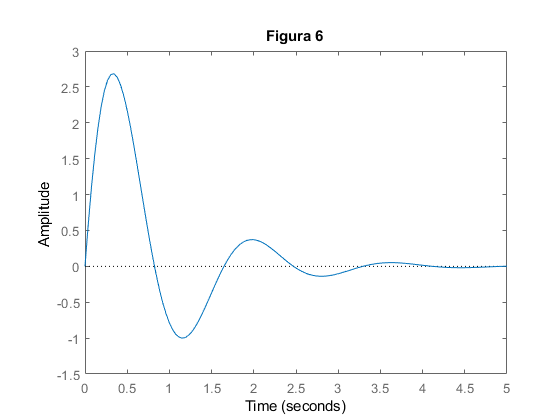

%para fazer a transformada inversa de laplace, precisamos escrever G2(s) na
%forma simbolica
g2

syms s t;
g2t = ilaplace(16/(s^2+2.4*s+16)); %retorna a função simbolica da transformada inversa de laplace de g2(s)
figure();
fplot(g2t, [0 6])
ylim([-1.5 3])
title('Resposta ao impulso de g2')

g2 =
 
         16
  ----------------
  s^2 + 2.4 s + 16
 
Continuous-time transfer function.



grid on;

8) Observe a resposta ao degrau do item 3) e escolha um tempo de amostragem de 10% do valor do tempo de estabilização medido. Discretize o modelo g2 usado com o comando c2d e plote no mesmo gráfico a resposta ao degrau dos sistemas contínuo e discreto.

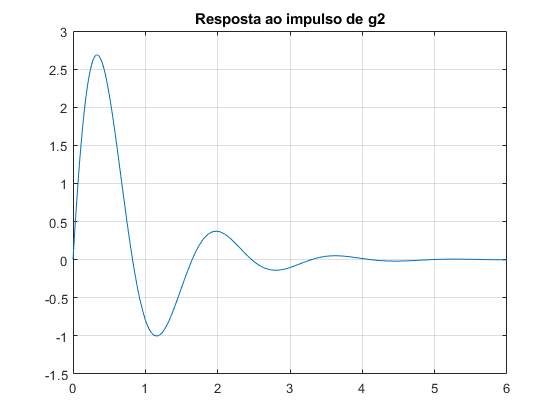

 % Coloque aqui os comandos para discretizar g2 e plotar respostas 
figure
hold on;
amostragem = 0.1*3.33;
g2d = c2d(g2, amostragem); %Retorna G2 discretizada no tempo de amostragem supracitado
step(g2);

step(g2d);
title('Figura 7')

Seja o sistema massa-mola-amortecedor mostrado na figura 7 e a equação diferencial que gere seu comportamento. $X$é o deslocamento em metros e $F$a força aplicada em Newtons.


$$m\ddot{x}+b\dot{x}+kx=f(t)$$


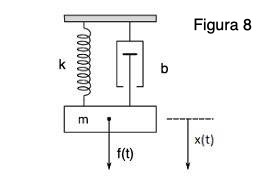

9) Obtenha a função de transferência $G\left(s\right)=\frac{X\left(s\right)}{F\left(s\right)}$ e faça sua simulação ao degrau com os parâmetros M,K,B definidos abaixo. Qual o deslocamento máximo da massa e qual seu tempo de estabelecimento?

Resposta:

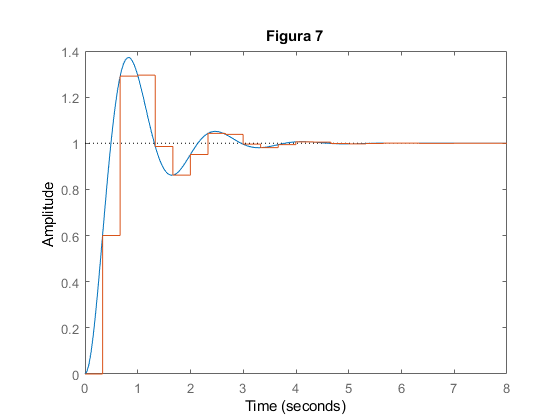

M=I;
K=M*wn^2
B=2*M*zeta*wn;
G_F = tf(1,[M B K])

figure()
step(G_F)

title('Figura 9');
grid on
stepinfo(G_F)

10) Seja o diagrama de blocos mostrado abaixo.

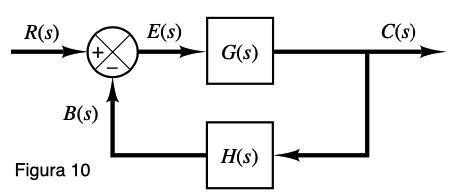

Obtenha:


$$\frac{E\left(s\right)}{R\left(s\right)}$$
 


$$\frac{C\left(s\right)}{R\left(s\right)}$$


Do diagrama de blocos, temos as seguintes relações: 

i) C(s) = E(s)G(s)

ii) E(s) = R(s) - B(s)

iii) B(s) = H(s)C(s)


$$C\left(s\right)=G\left(s\right)\left\lbrack R\left(s\right)-H\left(s\right)C\left(s\right)\right\rbrack$$



$$\frac{C\left(s\right)}{R\left(s\right)}=\frac{G\left(s\right)}{1+G\left(s\right)H\left(s\right)}$$



$$\frac{E\left(s\right)}{R\left(s\right)}=\frac{1}{1+G\left(s\right)H\left(s\right)}$$


11) Seja o sistema massa-mola-amortecedo do item 7. Obtenha o modelo em variáveis de estado definido pelas matrizes [A,B,C,D] de modo que $x_1 \left(t\right)$ seja a posição e $x_2 \left(t\right)$seja a velocidade. Aplique então um degrau e plote os dois estados, explicando seu comportamento. Dica: veja o comando tf2ss.

figure
title('Figura 11')

K = 224

[A,B,C,D] = tf2ss()

12) Seja gma definida abaixo.

gma=tf(wn^2*[1/p 1],[1 2*zeta*wn 0])

G_F =
 
            1
  ---------------------
  14 s^2 + 33.6 s + 224
 
Continuous-time transfer function.



Obtenha seus polos e zeros de malha aberta e de malha fechada.

Resposta:

Para malha aberta:


$$\begin{array}{l}
\mathrm{Polos}:\\
\mathrm{s²}+2,4s=0\\
s_1 =-2,4\\
s_2 =0\\
\mathrm{Zeros}:\\
0\ldotp 5926s+16=0\;\\
s=-26,9997
\end{array}$$


Para malha fechada:


$$\mathrm{gmf}=\frac{\mathrm{gma}}{1+\mathrm{gma}}$$


gmf = gma/(1+gma)


$$\begin{array}{l}
\mathrm{Zeros}:\\
0,5926\mathrm{s³}+17,42\mathrm{s²}+38,4s=0\\
s_1 =-2,4\\
s_2 =-26,995\\
s_3 =0\\
\mathrm{Polos}:\\
s^4 +5,393s^3 +23,18s^2 +38,4s=0\\
s_1 =-2,66\\
s_2 =0\\
s_3 -1,64-3,4i\\
s_4 =-1,64+3,4i
\end{array}$$


Análise do erro em regime. Seja o diagrama de blocos mostrado abaixo com G(s) definida abaixo.

G=tf(p^2,poly(-[p p]))

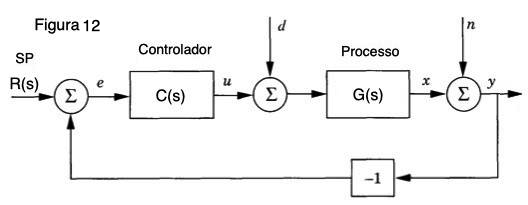

13. Qual o erro em regime para uma entrada degrau unitário caso $C\left(s\right)=K$?

Resposta: Considerando que não temos disturbios.

Primeiro devemos calcular a função de transferência de malha fechada:


$$T=\frac{C\left(s\right)G\left(s\right)}{1+C\left(s\right)G\left(s\right)}$$


Para a entrada ao degrau, a sua transformada de laplace é:


$$U\left(s\right)=\frac{1}{s}$$


O erro "e" é:


$$E\left(s\right)=U\left(s\right)-T\left(s\right)$$


O erro em regime é dado pelo limite de s tendendo a 0 de sE(s), dessa forma temos:

$e_{\mathrm{ss}} =\underset{s\to 0}{\mathrm{lim}} \mathrm{sE}\left(s\right)=\underset{s\to 0}{\mathrm{lim}} s\left(\frac{1}{s}-\frac{C\left(s\right)G\left(s\right)}{1+C\left(s\right)G\left(s\right)}\right)$2

Mas C(s) = K, portanto


$$e_{\mathrm{ss}} =\underset{s\to 0}{\mathrm{lim}} \mathrm{sE}\left(s\right)=\underset{s\to 0}{\mathrm{lim}} s\left(\frac{1}{s}-\frac{K*G\left(s\right)}{1+K*G\left(s\right)}\right)$$


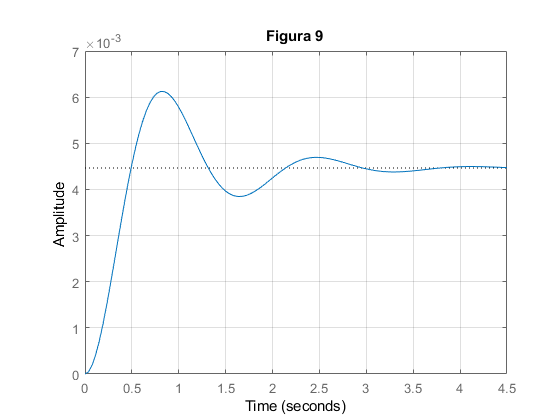

syms K_ K_p K_i K_soma
limit(s*(1/s +(K_*(729/(s^2+54*s+729))/(1+K_*729/(s^2+54*s+729)))))

Para C(s) = K, uma constante qualquer, o erro em regime da entrada ao degrau é igual a 1.

14. Repita o item 11 para $C\left(s\right)=K_p +\frac{K_I }{s}$

Resposta:

Substituindo para o novo controlador, temos:


$$e_{\mathrm{ss}} =\underset{s\to 0}{\mathrm{lim}} \mathrm{sE}\left(s\right)=\underset{s\to 0}{\mathrm{lim}} s\left(\frac{1}{s}-\frac{\left(K_p +\frac{K_I }{s}\right)*G\left(s\right)}{1+\left(K_p +\frac{K_I }{s}\right)*G\left(s\right)}\right)$$


K_soma = K_p + K_i/s;

ans = struct with fields:
        RiseTime: 0.3309
    SettlingTime: 2.8075
     SettlingMin: 0.0038
     SettlingMax: 0.0061
       Overshoot: 37.1410
      Undershoot: 0
            Peak: 0.0061
        PeakTime: 0.8059


limit(s*(1/s +(K_soma*(729/(s^2+54*s+729))/(1+K_soma*729/(s^2+54*s+729)))))

Para C(s) = K, uma constante qualquer, o erro em regime da entrada ao degrau é igual a 1.

15. Caso um distúrbio $d\left(t\right)=1$ afete a malha de controle, como verificar seu efeito no erro E(s) para um dado controlador C(s)?

Ilustre aplicando o degrau em $d\left(t\right)=1$e plotando $y(t)$, com $r(t)=0$. Use $C(s)=K$, onde K garante estabilidade.

Resposta:

A

16. Verifique os valores de K para estabilidade de $\frac{Y(s)}{R(s)}=\frac{KG_3(s)}{1+KG_3(s)$ (g3 foi definida em init).

Resposta:

g3

gma =
 
  0.5926 s + 16
  -------------
   s^2 + 2.4 s
 
Continuous-time transfer function.



gmf =
 
    0.5926 s^3 + 17.42 s^2 + 38.4 s
  ------------------------------------
  s^4 + 5.393 s^3 + 23.18 s^2 + 38.4 s
 
Continuous-time transfer function.



G =
 
        729
  ----------------
  s^2 + 54 s + 729
 
Continuous-time transfer function.



$$ans = 1$$

$$ans = 1$$

g3 =
 
              19683
  -----------------------------
  s^3 + 81 s^2 + 2187 s + 19683
 
Continuous-time transfer function.




$$\mathrm{gmf}=\frac{\mathrm{g3}*K}{1+\mathrm{g3}*K}$$



$$\mathrm{Para}\;\mathrm{verificar}\;a\;\mathrm{estabilidade},\mathrm{devemos}\;\mathrm{calcular}\;\mathrm{pelo}\;\mathrm{método}\;\mathrm{de}\;\mathrm{Routh}:$$



$$\begin{array}{l}
s^3 \;\;\;\;\;\;\\
s^2 \;\;\;\;\;\;\\
s^1 \;\;\;\;\;\\
s^0 
\end{array}$$
